clear; close all; clc; % initializes environment

# 座標軸の回転と座標の変換

## 本章の目的

正射影ベクトルの長さの分散$S=\left(u,\mathit{Vu}\right)$は，分散共分散行列$V$の固有値分解$V=\mathit{QD}Q^T$を用いて，$S=\left(u\prime ,\mathit{Du}\prime \right)$と表すことができます．ただし，$u\prime =Q^T u$です．前章では，行列$Q$を用いた$u\prime =Q^T u$という写像の幾何学的なイメージを解説しました．行列$Q$は直交行列になるため，その写像は回転や反転を表します．$u\prime =Q^T u$で表される写像は，$S=\left(u,\mathit{Vu}\right)$のグラフを回転させ$S=\left(u\prime ,\mathit{Du}\prime \right)$で表されるグラフにします．その結果，$S=\left(u\prime ,\mathit{Du}\prime \right)$は座標軸上で最大値や最小値をとるようになります．また，PCAにおける主成分スコアは行列$Q^T$によるデータ行列$X$の回転$X\prime =Q^T X$に対応することを解説しました．すなわち$X\prime =Q^T X$は，$X\prime$がもっとも広がる方向と座標軸が一致するように，データ行列$X$を回転させる操作といえます．

本章では，行列による回転の幾何学的な解釈として「座標軸の回転」とその結果として起こる「座標の変換」を紹介します．

## データの準備

### データの読み込み

引き続き，「米国３２９都市における生活満足度」のデータセットを用います．また，「健康」と「芸術」に関する指標を用いて，変数とする二変量データとして解説していきます．さらに，説明を簡単にするために，平均値が０，標準偏差が１になるように正規化しておきます．

load cities.mat;
scores_health_norm = normalize(ratings(:, 3)); % extracts scores on healt (the 3rd  column) and normalizes it
scores_arts_norm = normalize(ratings(:, 7)); % extracts scores on arts (the 7th column) and normalizes it

### データ行列の作成

説明のため，データ行列$X$を定義します．各行が「健康」および「芸術」に関する正規化された評価値に対応し，各列が観測に対応します．

X = [scores_health_norm scores_arts_norm]'

X =    -0.9459    0.4689   -0.5660    0.2445    0.6653   -0.5441   -0.5630   -0.2201   -0.7515   -0.5152    0.8367   -0.5830   -0.6039   -0.3646    1.3183   -0.5860   -0.3517    0.0182   -0.5790    2.0032   -0.5471    0.6104    0.0172   -0.4025   -0.7634    2.3691   -0.4045   -0.8412   -0.2849   -0.5680   -0.3238   -0.9429   -0.6139    1.4708   -0.7046   -0.7425   -0.1782    0.5047   -0.3806   -0.4534   -0.3696   -0.7305    4.1029   -0.2231   -0.8502   -0.7455   -0.8731    1.3602   -0.2101   -0.2689
   -0.4642    0.5198   -0.6277    0.3240    0.2898   -0.6068   -0.1762   -0.3584   -0.6236   -0.4127    0.5345   -0.1734   -0.5861   -0.6423    0.9496   -0.6210   -0.4276   -0.3791    0.0851    0.9496   -0.5450   -0.4532    0.1521    0.4748   -0.4155    1.4297   -0.2490    0.2340   -0.6025   -0.2921   -0.4021   -0.3983   -0.6617    1.3255   -0.5111   -0.5325   -0.3343    0.1739   -0.4179   -0.2152   -0.3621   -0.1650    3.8539    0.1103   -0.6456   -0.3543   -0.5964    1.1238   -0.5680   -0

データ行列$X$の$i$番目の観測を$x^{\left(i\right)} =\left\lbrack \begin{array}{c}
{\mathrm{x}}_1^{\left(\mathrm{i}\right)} \\
{\mathrm{x}}_2^{\left(\mathrm{i}\right)} 
\end{array}\right\rbrack$と表します．ここで，${\mathrm{x}}_1^{\left(\mathrm{i}\right)}$および${\mathrm{x}}_2^{\left(\mathrm{i}\right)}$はそれぞれデータ行列$X$の$i$番目の観測における一番目の変数（「健康」）と二番目の変数（「芸術」）の標準化された評価値です．

### 分散共分散行列

データ行列$X$の分散共分散行列$V$は

V = cov(X',1)

V =     0.9970    0.8632
    0.8632    0.9970


となります．

### 分散共分散行列$V$の固有ベクトルおよび固有値

eig()関数を用いて以下のように求めることができました．

[Q,D] = eig(V)

Q =     0.7071   -0.7071
   -0.7071   -0.7071


D =     0.1338         0
         0    1.8601


ここで，行列$Q$の各列が分散共分散行列$V$の固有ベクトルです．また，行列$D$は対角成分が固有値となる対角行列です．対角成分が左上から降順に並ぶように並び替えます．

[d,ind] = sort(diag(D),'descend');
D = diag(d)

D =     1.8601         0
         0    0.1338


固有ベクトルも対応するように，$Q$の列を左側から順次並べ替えていきます．

Q = Q(:,ind)

Q =    -0.7071    0.7071
   -0.7071   -0.7071


## 基底ベクトルと座標

座標もしくは座標軸の回転の話をする前に，ここでは基底ベクトルと座標系について解説します．

### 基底と基底ベクトル

これまで，$x=\left\lbrack \begin{array}{c}
{\mathrm{x}}_1 \\
{\mathrm{x}}_2 
\end{array}\right\rbrack$のようなベクトル表記は二次元平面上にある点の座標，もしくは，原点$O$から座標までの矢印として扱ってきました．しかし，ベクトルには特別なベクトルがあります．それが**基底ベクトル**です．一般に，有限個のベクトルの組$\left\lbrace e^{\left(1\right)} ,e^{\left(2\right)} ,\cdots ,e^{\left(n\right)} \right\rbrace$が以下の性質を満たすとき，その組を**基底**といいますまた，本稿ではそれぞれのベクトルを**基底ベクトル**と呼ぶことにします．

- 線型独立である

- それらの線型結合$\sum_{i=1}^n {\mathrm{a}}_{\mathrm{i}} e^{\left(i\right)}$によって任意のベクトルを表すことができる

ここで，ベクトルの組$<e^{\left(1\right)} ,e^{\left(2\right)} ,\cdots ,e^{\left(n\right)} >$が線型独立とは，ベクトル$e^{\left(1\right)} ,e^{\left(2\right)} ,\cdots ,e^{\left(n\right)}$の線型結合$\sum_{i=1}^n {\mathrm{a}}_{\mathrm{i}} e^{\left(i\right)}$において，


$$\sum_{i=1}^n {\mathrm{a}}_{\mathrm{i}} e^{\left(i\right)} =0$$


となるのは${\mathrm{a}}_1 ={\mathrm{a}}_2 =\cdots ={\mathrm{a}}_{\mathrm{n}} =0$のときのみであるとき，ベクトルの組$\left\lbrace e^{\left(1\right)} ,e^{\left(2\right)} ,\cdots ,e^{\left(n\right)} \right\rbrace$は線型独立または一次独立であるといいます．すなわち，ベクトルの組のうちどれか一つのベクトルをそのほかのベクトルの線型結合として


$${\mathrm{a}}_1 e^{\left(1\right)} =\sum_{i=2}^n {\mathrm{a}}_{\mathrm{i}} e^{\left(i\right)}$$


のように表すことができない組のことをいいます（等号が成り立つのは${\mathrm{a}}_1 ={\mathrm{a}}_2 =\cdots ={\mathrm{a}}_{\mathrm{n}} =0$のときのみ）．

たとえば，ベクトル$e^{\left(1\right)} =\left\lbrack \begin{array}{c}
1\\
0
\end{array}\right\rbrack$および$e^{\left(2\right)} =\left\lbrack \begin{array}{c}
0\\
1
\end{array}\right\rbrack$を考えてみます．まず，ベクトル$e^{\left(1\right)} =\left\lbrack \begin{array}{c}
1\\
0
\end{array}\right\rbrack$および$e^{\left(2\right)} =\left\lbrack \begin{array}{c}
0\\
1
\end{array}\right\rbrack$の線型結合${\mathrm{a}}_1 e^{\left(1\right)} +{\mathrm{a}}_2 e^{\left(2\right)}$において，


$${\mathrm{a}}_1 e^{\left(1\right)} +{\mathrm{a}}_2 e^{\left(2\right)} =0$$


となるのは${\mathrm{a}}_1 ={\mathrm{a}}_2 =0$のときのみです．したがって，ベクトルの組$\left\lbrace e^{\left(1\right)} ,e^{\left(2\right)} \right\rbrace$は線型独立です．

また，任意のベクトル$x=\left\lbrack \begin{array}{c}
{\mathrm{x}}_1 \\
{\mathrm{x}}_2 
\end{array}\right\rbrack$を，


$$\begin{array}{l}
x={\mathrm{x}}_1 e^{\left(1\right)} +{\mathrm{x}}_2 e^{\left(2\right)} \\
\;\;={\mathrm{x}}_1 \left\lbrack \begin{array}{c}
1\\
0
\end{array}\right\rbrack +{\mathrm{x}}_2 \left\lbrack \begin{array}{c}
0\\
1
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
{\mathrm{x}}_1 \\
0
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
0\\
{\mathrm{x}}_2 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
{\mathrm{x}}_1 \\
{\mathrm{x}}_2 
\end{array}\right\rbrack 
\end{array}$$


と表すことができます．したがって，ベクトルの組$\left\lbrace e^{\left(1\right)} ,e^{\left(2\right)} \right\rbrace$は基底であり，$e^{\left(1\right)} =\left\lbrack \begin{array}{c}
1\\
0
\end{array}\right\rbrack$および$e^{\left(2\right)} =\left\lbrack \begin{array}{c}
0\\
1
\end{array}\right\rbrack$は基底ベクトルです．

### 基底ベクトルの幾何学的解釈

基底ベクトルを用いた任意のベクトルの表記


$$x={\mathrm{x}}_1 e^{\left(1\right)} +{\mathrm{x}}_2 e^{\left(2\right)}$$


は，ベクトル$e^{\left(1\right)}$の向きに長さ${\mathrm{x}}_1$だけ進んだベクトル${\mathrm{x}}_1 e^{\left(1\right)}$とベクトル$e^{\left(2\right)}$の向きに長さ${\mathrm{x}}_2$だけ進んだベクトル${\mathrm{x}}_2 e^{\left(2\right)}$の合成ベクトルとして図形的に解釈できます．下図は$x=\left\lbrack \begin{array}{c}
2\\
3
\end{array}\right\rbrack$としたときの様子を示しています．

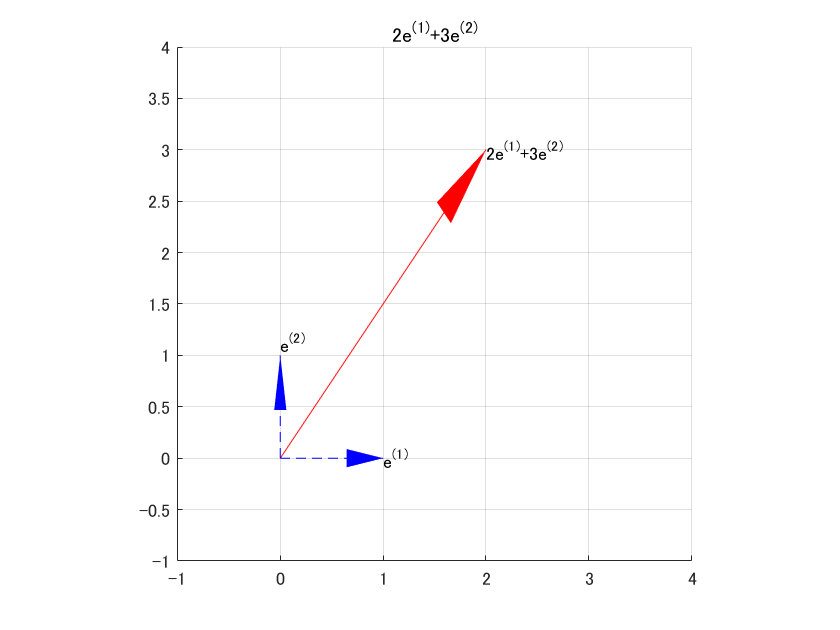

figure('Name','Fig.8-1: basis');
x = [2 3]';
e1 = [1 0]';
e2 = [0 1]';
x_e = [e1 e2]*x;
arrow3(zeros(1,2),x_e','r-',4); hold on;
arrow3(zeros(1,2),e1','b--',3);
arrow3(zeros(1,2),e2','b--',3);
grid on; axis([-1 4 -1 4]); axis square;
text(x_e(1),x_e(2),sprintf('%de^{(1)}+%de^{(2)}',x(1),x(2)));
text(e1(1),e1(2),'e^{(1)}');
text(e2(1),e2(2),'e^{(2)}','VerticalAlignment','bottom');
title('2e^{(1)}+3e^{(2)}');

### 基底と座標

たとえば，基底$\left\lbrace e^{\left(1\right)} ,e^{\left(2\right)} \right\rbrace$を用いて任意のベクトルを


$$x={\mathrm{x}}_1 e^{\left(1\right)} +{\mathrm{x}}_2 e^{\left(2\right)}$$


と表した場合，


$$x=\left\lbrack \begin{array}{c}
{\mathrm{x}}_1 \\
{\mathrm{x}}_2 
\end{array}\right\rbrack$$


というベクトルは，基底$<e^{\left(1\right)} ,e^{\left(2\right)} >$で定められる二次元平面の座標としてとらえることができます．言い換えると，基底はある空間の座標軸を定めるものと考えることができます．上記の例では，ベクトル$e^{\left(1\right)}$は二次元平面の横軸に対応させ，ベクトル$e^{\left(2\right)}$は縦軸に対応させています．基底$\left\lbrace e^{\left(1\right)} ,e^{\left(2\right)} \right\rbrace$を座標軸に対応させることで，その空間上の任意の点を$x={\mathrm{x}}_1 e^{\left(1\right)} +{\mathrm{x}}_2 e^{\left(2\right)}$として表すことができます．また，$x=\left\lbrack \begin{array}{c}
{\mathrm{x}}_1 \\
{\mathrm{x}}_2 
\end{array}\right\rbrack$のように，座標として特定することができます（このとき，基底ベクトルは省略されていることに注意してください）．

このように，座標とは基底が定まることによって決まります．基底のようなベクトル（またはスカラー）を用いて，点の位置を座標として表すシステムのことを座標系といいます．

### 複数の基底と座標

おなじ空間を表すときでも，基底の取り方は一通りではありません．たとえば，$\left\lbrace \left\lbrack \begin{array}{c}
-1\\
0
\end{array}\right\rbrack ,\left\lbrack \begin{array}{c}
0\\
-1
\end{array}\right\rbrack \right\rbrace$も二次元空間の基底です．また，$\left\lbrace \left\lbrack \begin{array}{c}
0\ldotp 2\\
0\ldotp 4
\end{array}\right\rbrack ,\left\lbrack \begin{array}{c}
0\ldotp 4\\
0\ldotp 2
\end{array}\right\rbrack \right\rbrace$も二次元空間になります．３つの基底を座標系とする図を以下に示します．

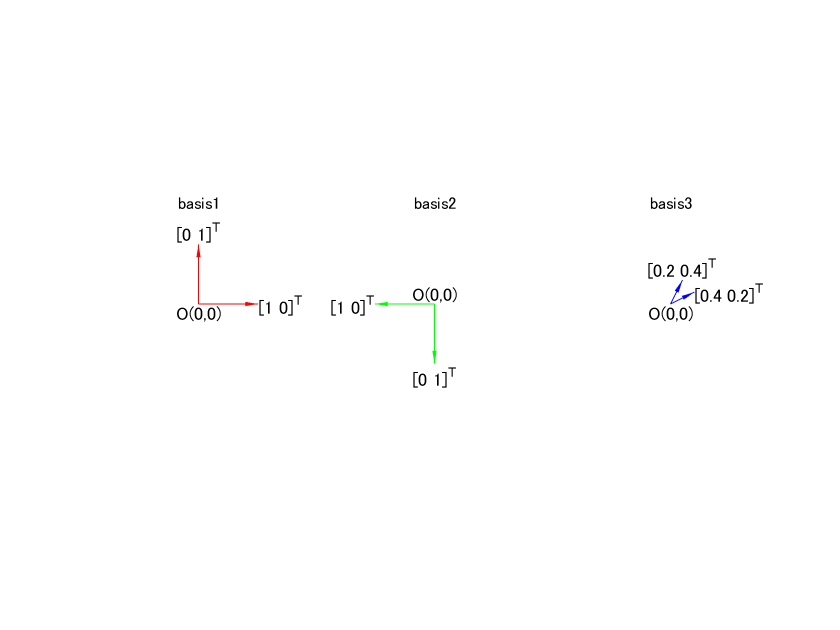

figure('Name','Fig.8-2: three bases');
basis1 = [1 0; 0 1];
subplot(1,3,1);
title('basis1'); hold on;
axis([-1.5 1.5 -1.5 1.5]); axis square; axis off;
text(0,0,'O(0,0)','HorizontalAlignment','center','VerticalAlignment','top');
arrow3([0 0],basis1(:,1)','r-'); text(basis1(1,1),basis1(2,1),'[1 0]^{T}');
arrow3([0 0],basis1(:,2)','r-'); text(basis1(1,2),basis1(2,2),'[0 1]^{T}','HorizontalAlignment','center','VerticalAlignment','bottom');

basis1 = [-1 0; 0 -1];
subplot(1,3,2);
title('basis2'); hold on;
axis([-1.5 1.5 -1.5 1.5]); axis square; axis off;
text(0,0,'O(0,0)','HorizontalAlignment','center','VerticalAlignment','bottom');
arrow3([0 0],basis1(:,1)','g-'); text(basis1(1,1),basis1(2,1),'[1 0]^{T}','HorizontalAlignment','right');
arrow3([0 0],basis1(:,2)','g-'); text(basis1(1,2),basis1(2,2),'[0 1]^{T}','HorizontalAlignment','center','VerticalAlignment','top');

basis1 = [0.4 0.2; 0.2 0.4];
subplot(1,3,3);
title('basis3'); hold on;
axis([-1.5 1.5 -1.5 1.5]); axis square; axis off;
text(0,0,'O(0,0)','HorizontalAlignment','center','VerticalAlignment','top');
arrow3([0 0],basis1(:,1)','b-'); text(basis1(1,1),basis1(2,1),'[0.4 0.2]^{T}');
arrow3([0 0],basis1(:,2)','b-'); text(basis1(1,2),basis1(2,2),'[0.2 0.4]^{T}','HorizontalAlignment','center','VerticalAlignment','bottom');

左図は$e^{\left(1\right)} =\left\lbrack \begin{array}{c}
1\\
0
\end{array}\right\rbrack$および$e^{\left(2\right)} =\left\lbrack \begin{array}{c}
0\\
1
\end{array}\right\rbrack$を表しています．真ん中の図は$\left\lbrack \begin{array}{c}
-1\\
0
\end{array}\right\rbrack$および$\left\lbrack \begin{array}{c}
0\\
-1
\end{array}\right\rbrack$を表しています．右図は$\left\lbrack \begin{array}{c}
0\ldotp 2\\
0\ldotp 4
\end{array}\right\rbrack$および$\left\lbrack \begin{array}{c}
0\ldotp 4\\
0\ldotp 2
\end{array}\right\rbrack$を表しています．いずれの図においても，ふたつのベクトルの組は二次元平面の座標を定める基底となりうることが確認できると思います．

二次元平面上のある一点を座標として定める場合，どの基底を用いた座標系かによって，その座標か変わります．たとえば，基底$\left\lbrace e^{\left(1\right)} ,e^{\left(2\right)} \right\rbrace$で定められる座標系において点$\mathrm{P}$の位置が座標$\left\lbrack \begin{array}{c}
1\\
1
\end{array}\right\rbrack$として表される場合，基底$\left\lbrace \left\lbrack \begin{array}{c}
-1\\
0
\end{array}\right\rbrack ,\left\lbrack \begin{array}{c}
0\\
-1
\end{array}\right\rbrack \right\rbrace$で定められる座標系での点$\mathrm{P}$の座標は$\left\lbrack \begin{array}{c}
-1\\
-1
\end{array}\right\rbrack$となります．同様に，基底$\left\lbrace \left\lbrack \begin{array}{c}
0\ldotp 2\\
0\ldotp 4
\end{array}\right\rbrack ,\left\lbrack \begin{array}{c}
0\ldotp 4\\
0\ldotp 2
\end{array}\right\rbrack \right\rbrace$で定められる座標系では$\left\lbrack \begin{array}{c}
1\ldotp 6667\\
1\ldotp 6667
\end{array}\right\rbrack$となります（下図参照）．

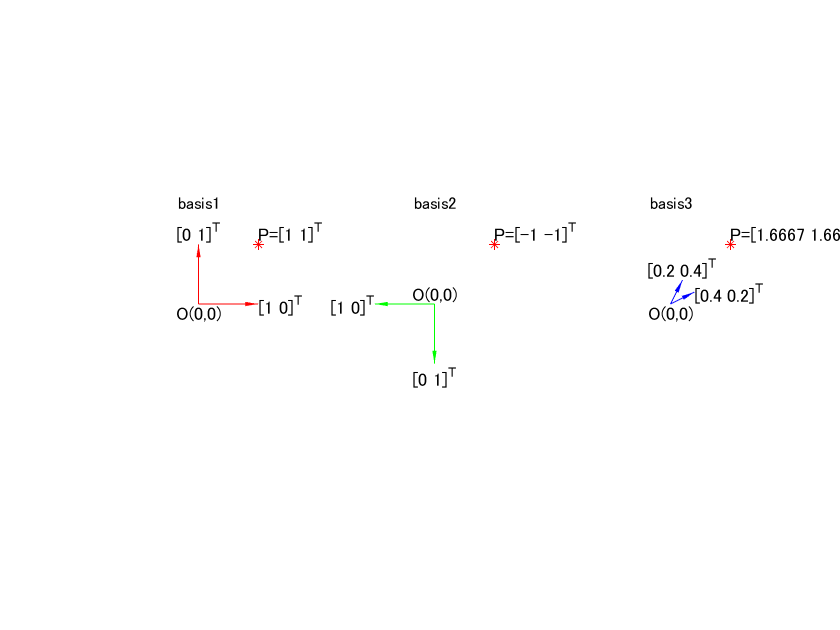

figure('Name','Fig.8-3: point P in the three bases');
basis1 = [1 0; 0 1];
subplot(1,3,1);
title('basis1'); hold on;
axis([-1.5 1.5 -1.5 1.5]); axis square; axis off;
text(0,0,'O(0,0)','HorizontalAlignment','center','VerticalAlignment','top');
arrow3([0 0],basis1(:,1)','r-'); text(basis1(1,1),basis1(2,1),'[1 0]^{T}');
arrow3([0 0],basis1(:,2)','r-'); text(basis1(1,2),basis1(2,2),'[0 1]^{T}','HorizontalAlignment','center','VerticalAlignment','bottom');
scatter(1,1,25,'r*'); text(1,1,'P=[1 1]^{T}','HorizontalAlignment','left','VerticalAlignment','bottom');

basis1 = [-1 0; 0 -1];
subplot(1,3,2);
title('basis2'); hold on;
axis([-1.5 1.5 -1.5 1.5]); axis square; axis off;
text(0,0,'O(0,0)','HorizontalAlignment','center','VerticalAlignment','bottom');
arrow3([0 0],basis1(:,1)','g-'); text(basis1(1,1),basis1(2,1),'[-1 0]^{T}','HorizontalAlignment','right');
arrow3([0 0],basis1(:,2)','g-'); text(basis1(1,2),basis1(2,2),'[0 -1]^{T}','HorizontalAlignment','center','VerticalAlignment','top');
scatter(1,1,25,'r*'); text(1,1,'P=[-1 -1]^{T}','HorizontalAlignment','left','VerticalAlignment','bottom');

basis1 = [0.4 0.2; 0.2 0.4];
subplot(1,3,3);
title('basis3'); hold on;
axis([-1.5 1.5 -1.5 1.5]); axis square; axis off;
text(0,0,'O(0,0)','HorizontalAlignment','center','VerticalAlignment','top');
arrow3([0 0],basis1(:,1)','b-'); text(basis1(1,1),basis1(2,1),'[0.4 0.2]^{T}');
arrow3([0 0],basis1(:,2)','b-'); text(basis1(1,2),basis1(2,2),'[0.2 0.4]^{T}','HorizontalAlignment','center','VerticalAlignment','bottom');
scatter(1,1,25,'r*'); text(1,1,'P=[1.6667 1.6667]^{T}','HorizontalAlignment','left','VerticalAlignment','bottom');

### 正規直交系と正規直交基底

互いに直交し（内積がゼロで），それぞれの長さが１であるベクトルの組を「正規直交系」といいます．上記の$\left\lbrace \left\lbrack \begin{array}{c}
1\\
0
\end{array}\right\rbrack ,\left\lbrack \begin{array}{c}
0\\
1
\end{array}\right\rbrack \right\rbrace$や$\left\lbrace \left\lbrack \begin{array}{c}
-1\\
0
\end{array}\right\rbrack ,\left\lbrack \begin{array}{c}
0\\
-1
\end{array}\right\rbrack \right\rbrace$はいずれの正規直交系です．また，$\left\lbrace \left\lbrack \begin{array}{c}
1\\
0
\end{array}\right\rbrack ,\left\lbrack \begin{array}{c}
0\\
1
\end{array}\right\rbrack \right\rbrace$や$\left\lbrace \left\lbrack \begin{array}{c}
-1\\
0
\end{array}\right\rbrack ,\left\lbrack \begin{array}{c}
0\\
-1
\end{array}\right\rbrack \right\rbrace$のようにそれらが基底となっている場合はとくに正規直交基底といいます．

### 分散共分散行列の固有ベクトルと正規直交基底

分散共分散行列$V$の異なる固有値に対する固有ベクトルは互いに直交します（第５章参照）．また，それぞれの固有値はその長さが１になるように規格化されています．したがって，分散共分散行列の固有ベクトルの組は正規直交基底です．

いま，$V=\left\lbrack \begin{array}{cc}
0\ldotp 9970 & 0\ldotp 8632\\
0\ldotp 8632 & 0\ldotp 9970
\end{array}\right\rbrack$のときを考えてみます．このときの固有ベクトルは$q^{\left(1\right)} =\left\lbrack \begin{array}{c}
-0\ldotp 7071\\
-0\ldotp 7071
\end{array}\right\rbrack$および$q^{\left(2\right)} =\left\lbrack \begin{array}{c}
0\ldotp 7071\\
-0\ldotp 7071
\end{array}\right\rbrack$です．

ふたつのベクトルの内積は

dot(Q(:,1),Q(:,2))

ans = 0

となります．また，それぞれの長さは

norm(Q(:,1))

ans = 1.0000

norm(Q(:,1))

ans = 1.0000

となり，固有ベクトルの組$\left\lbrace q^{\left(1\right)} ,q^{\left(2\right)} \right\rbrace$は正規直交基底であることがわかります．正規直交基底$\left\lbrace e^{\left(1\right)} =\left\lbrack \begin{array}{c}
1\\
0
\end{array}\right\rbrack ,e^{\left(2\right)} =\left\lbrack \begin{array}{c}
0\\
1
\end{array}\right\rbrack \right\rbrace$との比較を以下に示します．

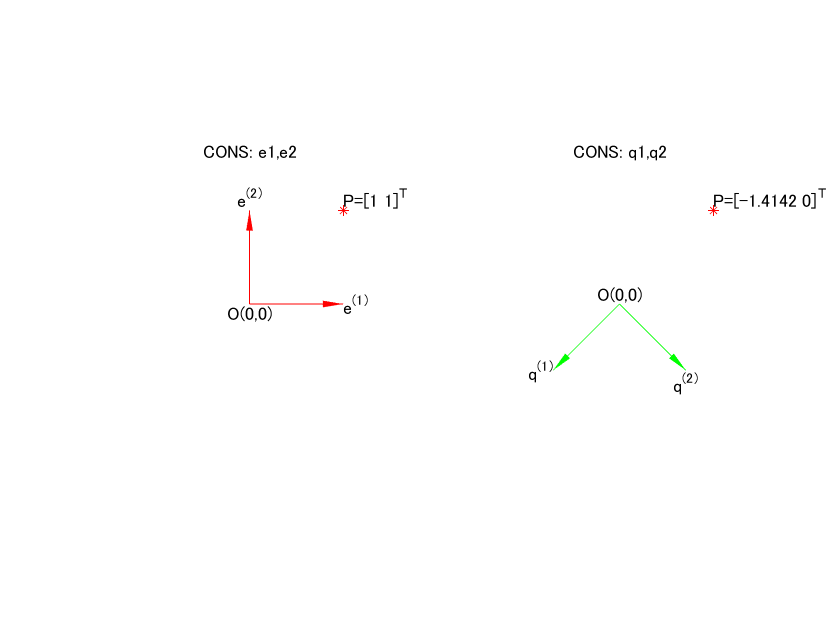

figure('Name','Fig.8-4: Complete OrthoNormal Systems');
basis1 = [1 0; 0 1];
subplot(1,2,1);
title('CONS: {e1,e2}'); hold on;
axis([-1.5 1.5 -1.5 1.5]); axis square; axis off;
text(0,0,'O(0,0)','HorizontalAlignment','center','VerticalAlignment','top');
arrow3([0 0],basis1(:,1)','r-'); text(basis1(1,1),basis1(2,1),'e^{(1)}');
arrow3([0 0],basis1(:,2)','r-'); text(basis1(1,2),basis1(2,2),'e^{(2)}','HorizontalAlignment','center','VerticalAlignment','bottom');
scatter(1,1,25,'r*'); text(1,1,'P=[1 1]^{T}','HorizontalAlignment','left','VerticalAlignment','bottom');

basis1 = Q;
subplot(1,2,2);
title('CONS: {q1,q2}'); hold on;
axis([-1.5 1.5 -1.5 1.5]); axis square; axis off;
text(0,0,'O(0,0)','HorizontalAlignment','center','VerticalAlignment','bottom');
arrow3([0 0],basis1(:,1)','g-'); text(basis1(1,1),basis1(2,1),'q^{(1)}','HorizontalAlignment','right');
arrow3([0 0],basis1(:,2)','g-'); text(basis1(1,2),basis1(2,2),'q^{(2)}','HorizontalAlignment','center','VerticalAlignment','top');
scatter(1,1,25,'r*'); text(1,1,'P=[-1.4142 0]^{T}','HorizontalAlignment','left','VerticalAlignment','bottom');

左図は正規直交基底$\left\lbrace e^{\left(1\right)} ,e^{\left(2\right)} \right\rbrace$を表しています（赤矢印）．右図は正規直交基底$\left\lbrace q^{\left(1\right)} ,q^{\left(2\right)} \right\rbrace$を表しています（緑矢印）．いずれの場合も，基底ベクトル同士が直交しているのがわかります．また，それぞれの図には点$\mathrm{P}$の位置と，それぞれの座標系での座標を示しています．前述したように，座標系（＝基底）が変われば，同じ点を示す座標も変わってきます．

## 座標系の変換と座標の変換

前セクションでは，座標系（基底）が変わると座標が変わることを指摘しました．ここでは，座標系が変わることで，座標がどのように変わるのかを具体例でみていきます．

### 行列$Q$による座標系の変換

ふたつの正規直交基底$\left\lbrace e^{\left(1\right)} ,e^{\left(2\right)} \right\rbrace$と$\left\lbrace q^{\left(1\right)} ,q^{\left(2\right)} \right\rbrace$との間の座標系の変換を考えます．

いま，二次元平面上の点$\mathrm{P}$が，正規直交基底$\left\lbrace e^{\left(1\right)} ,e^{\left(2\right)} \right\rbrace$で定められる座標系（単に座標系$\left\lbrace e^{\left(1\right)} ,e^{\left(2\right)} \right\rbrace$とします）において，$\left\lbrack \begin{array}{c}
{\mathrm{p}}_1 \\
{\mathrm{p}}_2 
\end{array}\right\rbrack$という座標で示されるとします．これは$\left\lbrace e^{\left(1\right)} ,e^{\left(2\right)} \right\rbrace$を用いて，


$${\mathrm{p}}_1 e^{\left(1\right)} +{\mathrm{p}}_2 e^{\left(2\right)} =\left\lbrack \begin{array}{cc}
e^{\left(1\right)}  & e^{\left(2\right)} 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
{\mathrm{p}}_1 \\
{\mathrm{p}}_2 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
{\mathrm{p}}_1 \\
{\mathrm{p}}_2 
\end{array}\right\rbrack$$


と表すことができます．ここで，$\left\lbrack \begin{array}{cc}
e^{\left(1\right)}  & e^{\left(2\right)} 
\end{array}\right\rbrack$はベクトル$e^{\left(1\right)}$と$e^{\left(2\right)}$をそれぞれ列にした行列で，単位行列$\left\lbrack \begin{array}{cc}
1 & 0\\
0 & 1
\end{array}\right\rbrack$になります．つぎに，同じ点$\mathrm{P}$が，正規直交基底$\left\lbrace q^{\left(1\right)} ,q^{\left(2\right)} \right\rbrace$で定められる座標系（単に座標系$\left\lbrace q^{\left(1\right)} ,q^{\left(2\right)} \right\rbrace$とします）において，$\left\lbrack \begin{array}{c}
{\mathrm{p}}_1 \prime \\
{\mathrm{p}}_2 \prime 
\end{array}\right\rbrack$という座標で示されるとします．これは$\left\lbrace q^{\left(1\right)} ,q^{\left(2\right)} \right\rbrace$を用いて，


$${\mathrm{p}}_1 \prime q^{\left(1\right)} +{\mathrm{p}}_2 \prime q^{\left(2\right)} =\left\lbrack \begin{array}{cc}
q^{\left(1\right)}  & q^{\left(2\right)} 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
{\mathrm{p}}_1 \prime \\
{\mathrm{p}}_2 \prime 
\end{array}\right\rbrack =Q\left\lbrack \begin{array}{c}
{\mathrm{p}}_1 \prime \\
{\mathrm{p}}_2 \prime 
\end{array}\right\rbrack$$


と表すことができます．いずれの座標系においても同じ点$\mathrm{P}$を表していますので，


$${\mathrm{p}}_1 e^{\left(1\right)} +{\mathrm{p}}_2 e^{\left(2\right)} ={\mathrm{p}}_1 \prime q^{\left(1\right)} +{\mathrm{p}}_2 \prime q^{\left(2\right)}$$


が成り立ちます．すなわち，


$$\left\lbrack \begin{array}{c}
{\mathrm{p}}_1 \\
{\mathrm{p}}_2 
\end{array}\right\rbrack =Q\left\lbrack \begin{array}{c}
{\mathrm{p}}_1 \prime \\
{\mathrm{p}}_2 \prime 
\end{array}\right\rbrack$$


となります．これは，座標系を正規直交基底$\left\lbrace q^{\left(1\right)} ,q^{\left(2\right)} \right\rbrace$から$\left\lbrace e^{\left(1\right)} ,e^{\left(2\right)} \right\rbrace$に変換した際の，座標の変換式を表します．たとえば，座標系$\left\lbrace q^{\left(1\right)} ,q^{\left(2\right)} \right\rbrace$において座標$\left\lbrack \begin{array}{c}
-1\ldotp 4142\\
0
\end{array}\right\rbrack$で示される点は，座標系$\left\lbrace e^{\left(1\right)} ,e^{\left(2\right)} \right\rbrace$において

Q*[-1.4142 0]'

という座標で表されます（図８－４参照）．模式的に表すと


$$\left\lbrace q^{\left(1\right)} ,q^{\left(2\right)} \right\rbrace \Longrightarrow^Q \left\lbrace e^{\left(1\right)} ,e^{\left(2\right)} \right\rbrace$$


という変換に相当します．また，$Q$は直交行列であることから，


$$\left\lbrack \begin{array}{c}
{\mathrm{p}}_1 \prime \\
{\mathrm{p}}_2 \prime 
\end{array}\right\rbrack =Q^T \left\lbrack \begin{array}{c}
{\mathrm{p}}_1 \\
{\mathrm{p}}_2 
\end{array}\right\rbrack$$


も成り立ちます．これは座標系$\left\lbrace e^{\left(1\right)} ,e^{\left(2\right)} \right\rbrace$から$\left\lbrace q^{\left(1\right)} ,q^{\left(2\right)} \right\rbrace$への変換


$$\left\lbrace e^{\left(1\right)} ,e^{\left(2\right)} \right\rbrace \Longrightarrow^{Q^T } \left\lbrace q^{\left(1\right)} ,q^{\left(2\right)} \right\rbrace$$


を表します．たとえば，座標系$\left\lbrace e^{\left(1\right)} ,e^{\left(2\right)} \right\rbrace$において$\left\lbrack \begin{array}{c}
1\\
1
\end{array}\right\rbrack$で示される点は，座標系$\left\lbrace q^{\left(1\right)} ,q^{\left(2\right)} \right\rbrace$において

Q'*[1 1]'

ans =     1.0000
    1.0000


ans =    -1.4142
   -0.0000


という座標になります（図８－４参照）．

### これまでのまとめ